# Optimal Estimation - Homework 3

### Tanner Koza

## Problem 1

Kalman Filter at its best – simulation (actually the Kalman filter is also quite reliable when we have an excellent model and low noise sensors).  Suppose we have a 2nd order system that we are regulating about zero (position and velocity) by wrapping an “optimal” control loop around the system.  The new dynamics of the continuous time system are given by the closed-loop A matrix:


$$A_{CL}=\left[\matrix{0 & 1 \cr
-1 & -1.4}\right]$$


Suppose our measurement is simply position (C=[1 0]).  There is a white noise process disturbance (force, Bw=[0 1]T) acting on the controlled system. 

### Find:

- **Part A:** Simulate the controlled system with the disturbance force (1σ=2) and a sampled sensor noise (1σ=1) for 100 seconds at a 10 Hz sample rate.

- **Part B: **What is $Q$, $Q_D$,and $R_D$?

- **Part C: **Calculate the steady state Kalman gain for the system.  This can be done in one of many ways: iterate the kalman filter until it converges, dlqe.m, dare.m, kalman.m, dlqr.m (+ predictor to current estimator trick), etc.  What is the steady state covariance of the estimates after the time update, $P^-$, as well as after the measurement update, $P^+$.  Where are the poles of the estimator?

- **Part D: **Now use the steady state kalman filter to generate an estimate ($\hat{x}$ and $\hat{\dot{x}}$) of the 2 states over time.  Calculate the norm of the standard deviation of the errors for each state.


$$N = \sqrt{(std(\dot{x}-\hat{\dot{x}}))^2+(std(x-\hat{x}))^2}$$


- **Part E: **Change the ratio of the $Q$ and $R_D$ weights in the Kalman filter design (and repeat part d with the new Kalman gain but DO NOT regenerate a new $x$ and $\dot{x}$) and determine the effect on the estimation errors. For what ratio of $Q$ to $R_D$ are the errors minimized?  Note: Often in practice we do not know the actual $Q$ and $R_D$ so these tend to be “tuning” parameters we can use to tune our filter.  However, according to Kalman the estimation errors are only minimized if we use the $Q$ and $R_D$ of the physical system.

### Solution: 

- **Part A: **The system was simulated with the following code.

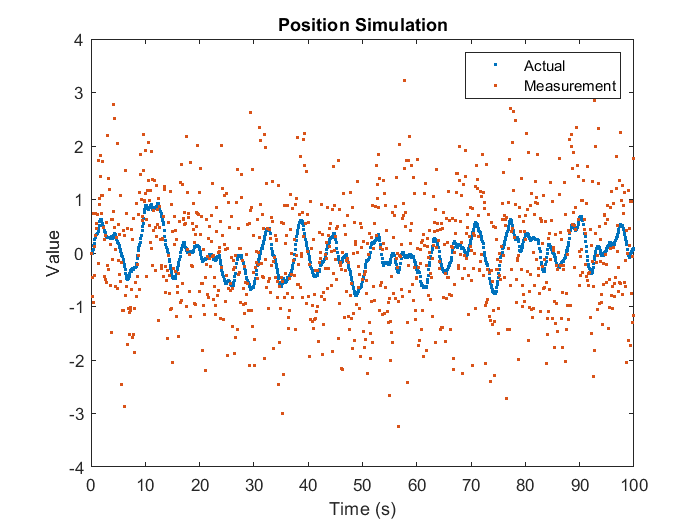

% Simulation Initialization
t_end = 100;
dt = 0.1;
t = dt:dt:t_end;
numSamps = length(t);

% Model Initialization
A_CL = [0 1; -1 -1.4];
A_D = expm(A_CL*dt);
C = [1 0];
B_W = [0; 1];

% Preallocation
x = zeros(2, numSamps);
y = zeros(numSamps,1);

for i = 1:numSamps-1
    
    % Continuous Simulation
    x_dot = A_CL * x(:,i) + B_W * (2*randn);
    x(:,i+1) = x(:,i) + x_dot * dt;

    % Measurement Simulation
    y(i+1) = x(1,i+1) + randn;
    
end

% Simulation Plotting
figure
plot(t,x(1,:),'.')
hold on
plot(t,y,'.')
title('Position Simulation')
legend('Actual', 'Measurement')
xlabel('Time (s)')
ylabel('Value')

- **Part B: **$Q$ is equivalent to $E[ww^T]$ which is the variance associated with the process noise. Therefore, $Q=4$. $Q_D$ is equivalent to $B_wQB_w^T\delta t$. Therefore, $Q_D$ is:


$$Q_D = \left[\matrix{0&0\cr0&0.4}\right]
$$


$R_D$ is equivalent to the measurement noise variance. Therefore, $R_D=1$.

Q = 4;
Q_D = B_W*Q*B_W'*dt;
R_D = 1;

- **Part C: **The steady-state Kalman gain was determined by creating the Kalman filter and recording the value of the gain when it converged. 


$$K_{ss} = \left[\matrix{0.1959\cr0.2094}\right]
$$


The following plots display estimate along with the prior and posterior covariance over time for $\hat{x}$ and $\hat{\dot{x}}$. The estimate is very noisy because of the low SNR and the current ratio between process and measurement covariance.

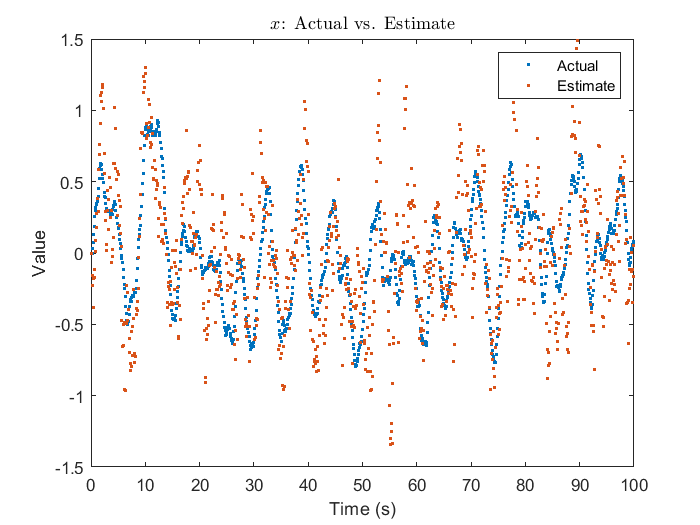

% Preallocation & Initialization
x_hat = zeros(2, numSamps);
P = eye(2);
priorP = zeros(numSamps,2);
postP = zeros(numSamps,2);

for i = 1:numSamps-1
    
    % Time Update (Propagation - a priori)
    x_hat(:,i+1) = A_D * x_hat(:,i);

    P = A_D * P * A_D' + Q_D;
    priorP(i+1,1) = P(1,1);
    priorP(i+1,2) = P(2,2);

    % Measurement Update (Correction - a posteriori)
    K = [0.1959;0.2094];%P * C' * (C*P*C' + R_D)^-1;

    x_hat(:,i+1) = x_hat(:,i+1) + K * (y(i+1) - C * x_hat(:,i+1));

    P = (eye(2) - K*C) * P;
    postP(i+1,1) = P(1,1);
    postP(i+1,2) = P(2,2);

end

% Steady-State Kalman Gain
K_SS = K;

% Steady-State Covariance
priorSS = priorP(end,:);
postSS = postP(end,:);

% Steady-State Estimator Poles
KFpoles = eig(A_D-K_SS*C);

% Position Estimate Plotting
figure
plot(t,x(1,:),'.')
hold on
plot(t,x_hat(1,:),'.')
title('$x$: Actual vs. Estimate','Interpreter',"latex")
legend('Actual','Estimate')
xlabel('Time (s)')
ylabel('Value')

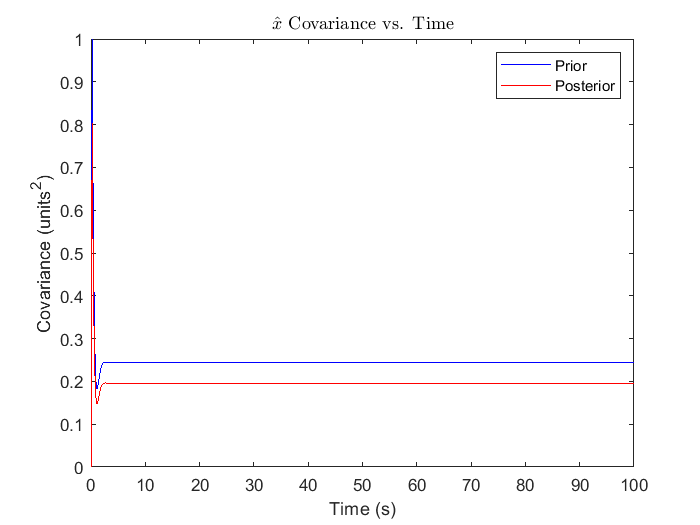


% Covariance Plotting
figure
plot(t,priorP(:,1), 'b');
hold on
plot(t,postP(:,1), 'r');
title('$\hat{x}$ Covariance vs. Time','Interpreter','latex')
legend('Prior','Posterior')
xlabel('Time (s)')
ylabel('Covariance (units^2)')

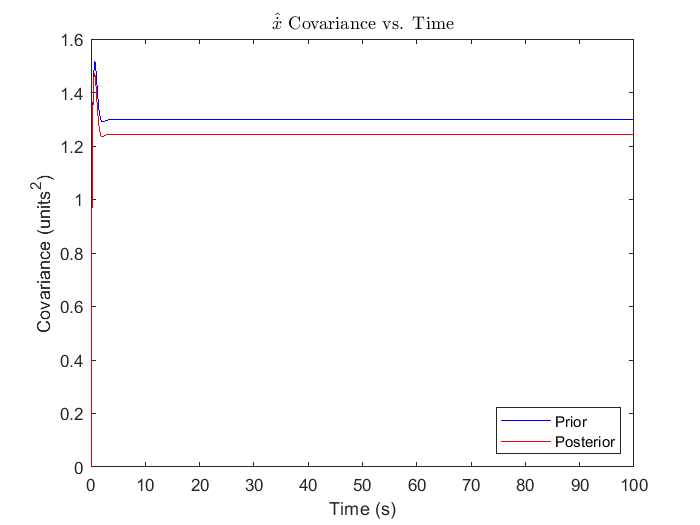

figure
plot(t,priorP(:,2), 'b');
hold on
plot(t,postP(:,2), 'r');
title('$\hat{\dot{x}}$ Covariance vs. Time','Interpreter','latex')
legend('Prior','Posterior','Location','southeast')
xlabel('Time (s)')
ylabel('Covariance (units^2)')

- **Part D: **The above code was ran and $N$ was determined to be 0.5466.

dx = x - x_hat;
std_x = std(dx,0,2);
N = vecnorm([std_x(1) std_x(2)]);

- **Part E: **The same code was ran again multiple times with the same simulated data and the ratio of $Q$ and $R_D$ was changed to minimize $N$. The minimized value of $N$ was 0.4403 and the ratio was 0.79. Decreasing the process noise covariance allowed for the $N$ to decrease.

## **Problem 2**

Download the data hw3_2 from the website.  The data is in the form [t  y].  Suppose we want to design an estimator to estimate the bias in the measurement $y$.  We believe that the bias ($x$) is constant so we use the model given by:


$$\dot{x} = 0$$



$$y_k = x_k +\nu_k$$



$$\nu \tilde{} N(0,1)$$


### Find:

- **Part A: **Run the Kalman filter estimator with $Q_D=0$.  What happens at t>100 seconds? Why?  Calculate the steady state Kalman gain $L_{SS}$.  Plot $L(k)$.  This is known as the filter “going to sleep” (becomes a least squares estimator).

- **Part B: **To offset this problem we will “tune” $Q_D$ to track the bias.  What is the effect of changing $Q_D$ on the ability to track the step change in the bias? (try values of $Q_D$ from 0.0001 to 0.01 and plot $L(k)$ as well as the estimate of the bias ($\hat{x}$).  What is the tradeoff?

- **Part C: **Now filter the measurement using the first order low-pass filter


$$H(z)=\frac{\sqrt{Q_D}}{z-(1-\sqrt{Q_D})$$


- **Part D: **How does this compare to the Kalman filter solution?

### Solution:

- **Part A: **At t > 100s the filter no longer tracks the dynamic bias. This is because a $Q_D$ of 0 essentially turns the Kalman filter into a least squares estimation that can only track a constant state. The filter is assuming there is no process noise in the dynamics, meaning the state cannot change. Therefore, the filter reacts poorly.

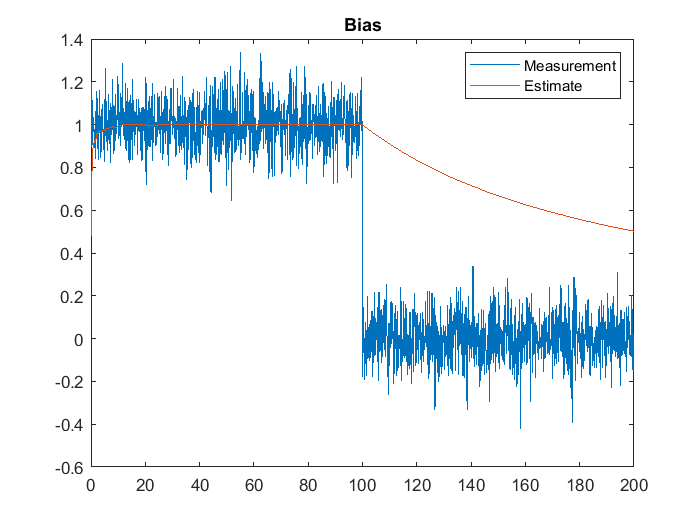

dt = 0.1;

A_C = 0;
A_D = expm(A_C * dt);
Q_D = 0;
H = 1;
R_D = 1;

data = readtable('hw3_2.txt');
data.Properties.VariableNames = {'t','y'};
numSamps = length(data.t);

xhat = zeros(numSamps,1);
x = 0;
P = 1;
K = zeros(numSamps,1);

for i = 1:numSamps
    
    x = A_D * x;
    
    P = A_D * P * A_D' + Q_D;
    
    K(i) = P * H' * (H*P*H' + R_D)^-1;
    
    xhat(i) = x + K(i) * (data.y(i) - H * x);
    
    P = (eye(1) - K(i)*H) * P;
    
    x = xhat(i);

end

figure
plot(data.t, data.y)
hold on
plot(data.t, xhat)
title('Bias')
legend('Measurement','Estimate')

- **Part B: T**he inclusion of process noise allows for the bias to be tracked when it changes. However, the certainty of the state estimate decreases ($P$ increases) and doesn't approach 0 as closely.

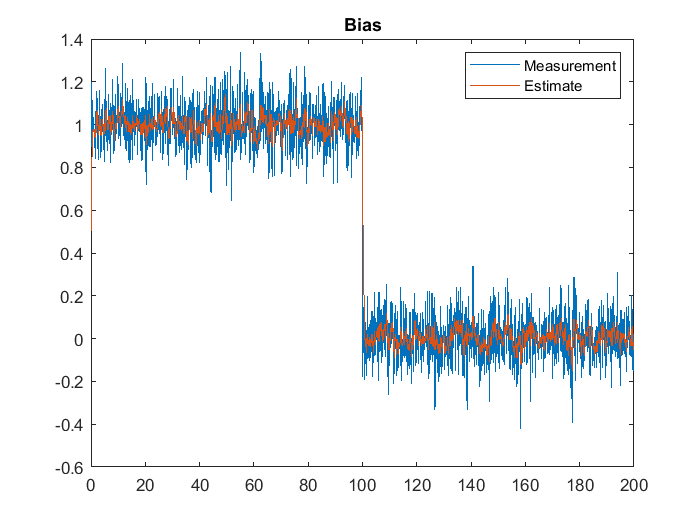

dt = 0.1;

A_C = 0;
A_D = expm(A_C * dt);
Q_D = 0.1;
H = 1;
R_D = 1;

data = readtable('hw3_2.txt');
data.Properties.VariableNames = {'t','y'};
numSamps = length(data.t);

xhat = zeros(numSamps,1);
x = 0;
P = 1;
K = zeros(numSamps,1);

for i = 1:numSamps
    
    x = A_D * x;
    
    P = A_D * P * A_D' + Q_D;
    
    K(i) = P * H' * (H*P*H' + R_D)^-1;
    
    xhat(i) = x + K(i) * (data.y(i) - H * x);
    
    P = (eye(1) - K(i)*H) * P;
    
    x = xhat(i);

end

figure
plot(data.t, data.y)
hold on
plot(data.t, xhat)
title('Bias')
legend('Measurement','Estimate')

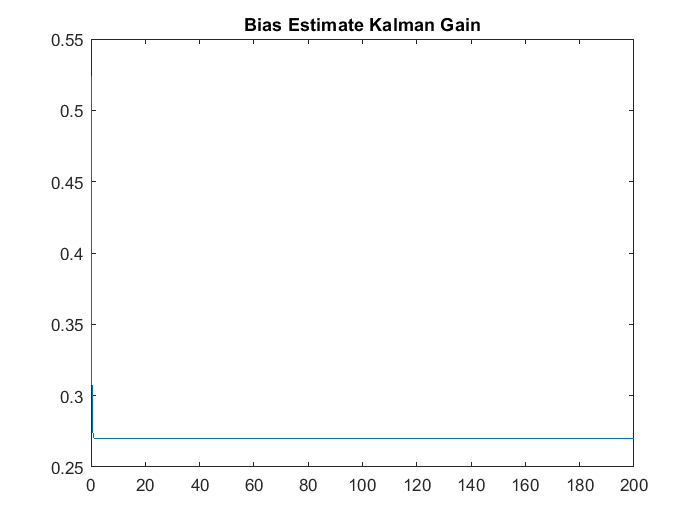


figure
plot(data.t,K)
title('Bias Estimate Kalman Gain')

- **Part C: **The following plot shows the Kalman filtered result against the low pass result.

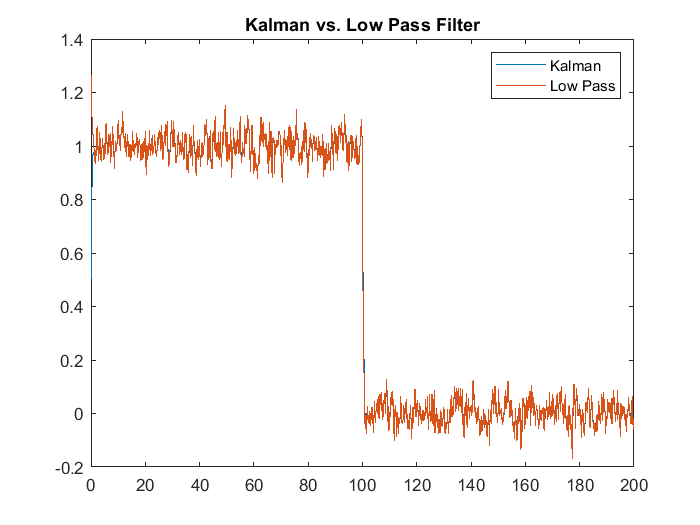

y_filt = filter(sqrt(Q_D),[1 -(1-sqrt(Q_D))],data.y,data.y(1));

figure
plot(data.t,xhat)
hold on
plot(data.t,y_filt)
title('Kalman vs. Low Pass Filter')
legend('Kalman','Low Pass')

- **Part D: **They are essentially the same because the Kalman filter is simply filtering the measurement. Process noise covariance was needed to track the state, but after that, the noise only decreases in amplitude which is all the lowpass filter does.

## **Problem 3**

Design a “Navigation” type Kalman filter to estimate the states [East, North, Radar_Bias, Psi, Gyro_Bias].  (Note: this is a non-linear problem that requires an Extended Kalman Filter (EKF) to do correctly.  However we can solve the problem in one of two ways: (i) linearize the equations about the nominal operating point and produce a constant $A$ matrix for that operating point, or (ii) simply update the $A$ matrix at every time step with our measurements or estimates.  Download the data hw3_3 from the website and run the filter sampled at 5 Hz.

### Find:

- **Part A: **How did you choose the covariance values for $Q_D$ (especially for the radar and gyro biases).

- **Part B: **How does the bias estimation compare to a Least Squares Solution.  How does the bias estimate compare to the Recursive Least Squares solution if you make the covariance (Qd) of the bias estimates equal to zero.

- **Part C: **Integrate the last 40 seconds of data to see how well you have estimated the biases. This can simply be done by “turning off” the measurements in the observation matrix!  Why do the bias estimates remain constant during the 40 second “outage"?

### Solution:

- **Part A: ** Knowing the model is fairly accurate, I made the process noise for each state very small (~0.001). For the biases, I made them close to 0 assuming the bias doesn't change much over time.

- **Part B: **The bias estimates were fairly noisy. I was unable to calculate with least squares and with recursive least squares they were constant after a few time steps. The plots of the Kalman filter and RLS estimates follow. They appear to estimate the same biases; however, the inlcusion of process noise makes the estimate noisy in the KF.

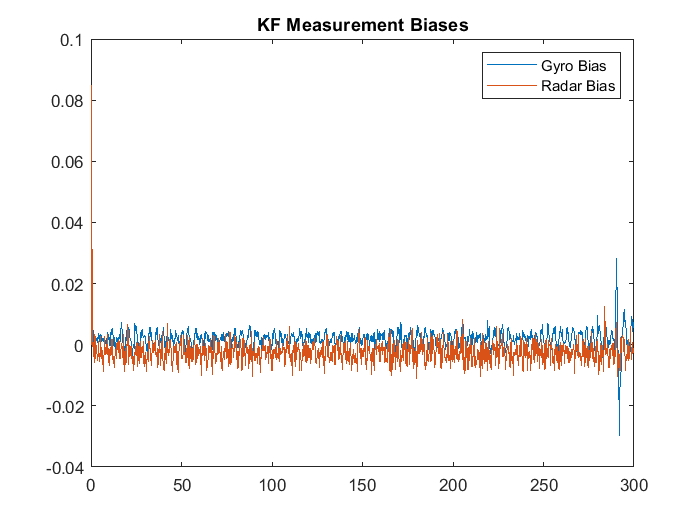

data = readtable('hw3_3.txt');
data.Properties.VariableNames = {'t','E','N','psi','gyro','v'};

% Time Initialization
numSamps = length(data.t);

% EKF Initialization
xhat = zeros(7,numSamps);
xhat(1,1) = data.E(1);
xhat(2,1) = data.N(1);
xhat(3,1) = data.psi(1);
xhat(4,1) = data.gyro(1);
xhat(5,1) = data.v(1);

procNoise = 0.01;
measNoise = .01;

P = eye(7); 

Q = procNoise * eye(7);
Q(6,6) = 0.0001;
Q(7,7) = 0.0001;

R = measNoise^2 * eye(5);

H = [eye(5) zeros(5,2)];
H(4,6) = 1;
H(5,7) = 1;

P_log = cell(numSamps,1);
P_log{1} = P;

% EKF
for i = 1:numSamps-1

    % Time Step Calculation
    dt = data.t(i+1) - data.t(i);

    % Time Update
    xhat(1,i+1) = xhat(1,i) + xhat(5,i)*sin(xhat(3,i))*dt;
    xhat(2,i+1) = xhat(2,i) + xhat(5,i)*cos(xhat(3,i))*dt;
    xhat(3,i+1) = xhat(3,i) + xhat(4,i)*dt;
    xhat(4,i+1) = xhat(4,i) - xhat(6,i);
    xhat(5,i+1) = xhat(5,i) - xhat(7,i);
    xhat(6,i+1) = xhat(6,i);
    xhat(7,i+1) = xhat(7,i);

    A = eye(7);
    A(1,3) = xhat(5,i)*cos(xhat(3,i))*dt;
    A(1,5) = sin(xhat(3,i))*dt;
    A(2,3) = -xhat(5,i)*sin(xhat(3,i))*dt;
    A(2,5) = cos(xhat(3,i))*dt;
    A(3,4) = dt;
    A(4,6) = -1;
    A(5,7) = -1;

    P = A*P*A' + Q;
    
    % Measurement Update
    K = P*H'*(H*P*H' + R)^-1;

    z = [data.E(i+1); data.N(i+1); data.psi(i+1); data.gyro(i+1);
        data.v(i+1)];

    xhat(:,i+1) = xhat(:,i+1) + K*(z - H*xhat(:,i+1));

    P = (eye(7) - K*H)*P;

    P_log{i+1} = P;

end

figure
plot(data.t,xhat(6,:))
hold on
plot(data.t,xhat(7,:))
title('KF Measurement Biases')
legend('Gyro Bias','Radar Bias')

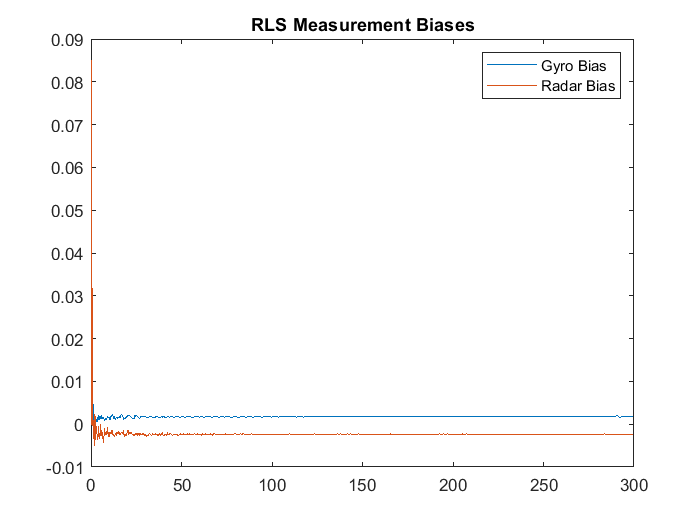


% Time Initialization
numSamps = length(data.t);

% EKF Initialization
xhat = zeros(7,numSamps);
xhat(1,1) = data.E(1);
xhat(2,1) = data.N(1);
xhat(3,1) = data.psi(1);
xhat(4,1) = data.gyro(1);
xhat(5,1) = data.v(1);

procNoise = 0.01;
measNoise = .01;

P = eye(7); 

Q = procNoise * eye(7);
Q(6,6) = 0.0000;
Q(7,7) = 0.0000;

R = measNoise^2 * eye(5);

H = [eye(5) zeros(5,2)];
H(4,6) = 1;
H(5,7) = 1;

P_log = cell(numSamps,1);
P_log{1} = P;

% EKF
for i = 1:numSamps-1

    % Time Step Calculation
    dt = data.t(i+1) - data.t(i);

    % Time Update
    xhat(1,i+1) = xhat(1,i) + xhat(5,i)*sin(xhat(3,i))*dt;
    xhat(2,i+1) = xhat(2,i) + xhat(5,i)*cos(xhat(3,i))*dt;
    xhat(3,i+1) = xhat(3,i) + xhat(4,i)*dt;
    xhat(4,i+1) = xhat(4,i) - xhat(6,i);
    xhat(5,i+1) = xhat(5,i) - xhat(7,i);
    xhat(6,i+1) = xhat(6,i);
    xhat(7,i+1) = xhat(7,i);

    A = eye(7);
    A(1,3) = xhat(5,i)*cos(xhat(3,i))*dt;
    A(1,5) = sin(xhat(3,i))*dt;
    A(2,3) = -xhat(5,i)*sin(xhat(3,i))*dt;
    A(2,5) = cos(xhat(3,i))*dt;
    A(3,4) = dt;
    A(4,6) = -1;
    A(5,7) = -1;

    P = A*P*A' + Q;
    
    % Measurement Update
    K = P*H'*(H*P*H' + R)^-1;

    z = [data.E(i+1); data.N(i+1); data.psi(i+1); data.gyro(i+1);
        data.v(i+1)];

    xhat(:,i+1) = xhat(:,i+1) + K*(z - H*xhat(:,i+1));

    P = (eye(7) - K*H)*P;

    P_log{i+1} = P;

end

figure
plot(data.t,xhat(6,:))
hold on
plot(data.t,xhat(7,:))
title('RLS Measurement Biases')
legend('Gyro Bias','Radar Bias')

- **Part C: **The bias estimates remain constant because the difference equation that propgates them assumes they do not change from time step to time step. Therefore, the previous constant estimate remains a good estimate as it is preserved moving forward in the absence of new measurements. 

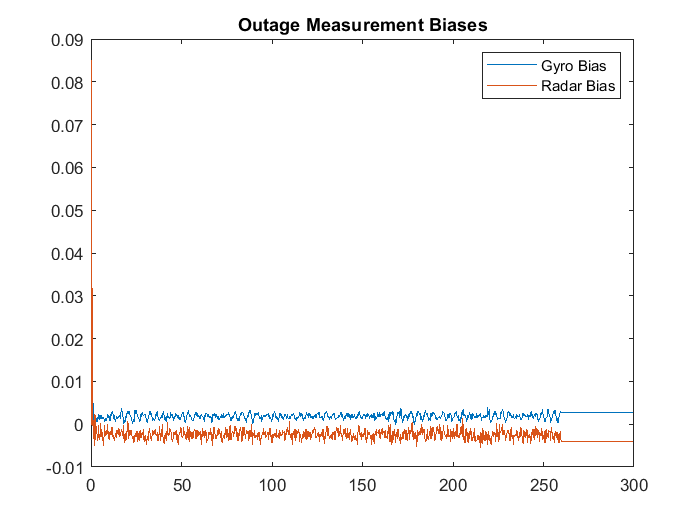

% Time Initialization
numSamps = length(data.t);

% EKF Initialization
xhat = zeros(7,numSamps);
xhat(1,1) = data.E(1);
xhat(2,1) = data.N(1);
xhat(3,1) = data.psi(1);
xhat(4,1) = data.gyro(1);
xhat(5,1) = data.v(1);

procNoise = 0.01;
measNoise = .01;

P = eye(7); 

Q = procNoise * eye(7);
Q(6,6) = 0.00001;
Q(7,7) = 0.00001;

R = measNoise^2 * eye(5);

H = [eye(5) zeros(5,2)];
H(4,6) = 1;
H(5,7) = 1;

P_log = cell(numSamps,1);
P_log{1} = P;

% EKF
for i = 1:numSamps-1

    % Time Step Calculation
    dt = data.t(i+1) - data.t(i);

    % Time Update
    xhat(1,i+1) = xhat(1,i) + xhat(5,i)*sin(xhat(3,i))*dt;
    xhat(2,i+1) = xhat(2,i) + xhat(5,i)*cos(xhat(3,i))*dt;
    xhat(3,i+1) = xhat(3,i) + xhat(4,i)*dt;
    xhat(4,i+1) = xhat(4,i) - xhat(6,i);
    xhat(5,i+1) = xhat(5,i) - xhat(7,i);
    xhat(6,i+1) = xhat(6,i);
    xhat(7,i+1) = xhat(7,i);

    A = eye(7);
    A(1,3) = xhat(5,i)*cos(xhat(3,i))*dt;
    A(1,5) = sin(xhat(3,i))*dt;
    A(2,3) = -xhat(5,i)*sin(xhat(3,i))*dt;
    A(2,5) = cos(xhat(3,i))*dt;
    A(3,4) = dt;
    A(4,6) = -1;
    A(5,7) = -1;

    P = A*P*A' + Q;
    
    % Measurement Update
    
    if i >= 1300
        H = zeros(5,7);
    end
    
    K = P*H'*(H*P*H' + R)^-1;
    
    z = [data.E(i+1); data.N(i+1); data.psi(i+1); data.gyro(i+1);
        data.v(i+1)];

    xhat(:,i+1) = xhat(:,i+1) + K*(z - H*xhat(:,i+1));

    P = (eye(7) - K*H)*P;

    P_log{i+1} = P;

end

figure
plot(data.t,xhat(6,:))
hold on
plot(data.t,xhat(7,:))
title('Outage Measurement Biases')
legend('Gyro Bias','Radar Bias')

## **Problem 4**

Estimator for Vehicle Dynamics. The yaw dynamics of a car (for a stability control system) can be described by the following model (at 25 m/s):


$$\dot{x}=\left[\matrix{-2.62 & 12 \cr -0.96 & -2}\right]\left[\matrix{\dot{\psi}\cr\beta}\right]+\left[\matrix{14\cr1}\right]\delta$$



$$y_k = \left[\matrix{1 & 0}\right]x_k+\nu_k$$


where:

$\dot{\psi} =$Vehicle Yaw Rate

$\beta=$Vehicle Side Slip Angle

$\delta=$Steer Angle

$\nu_k=$Sample Sensor Noise

### Find:

- **Part A: **Assuming we can only measure the yaw rate ($\nu_k\tilde{}N(0,0,1^2)$), design a Kalman filter to do full state estimation (select a reasonable $Q_D$).  Provide a unit step steer input and estimate both states.  On one page plot the actual states and estimated states (use subplot(2,2,n) for each of the two states).  Where are the steady state poles of the estimator?

Now, somebody has loaded the trunk of the vehicle with bricks, changing the CG of the vehicle so now the actual model (at 25 m/s) is: 


$$\dot{x}=\left[\matrix{-2.42 & 4 \cr -0.99 & -2}\right]\left[\matrix{\dot{\psi}\cr\beta}\right]+\left[\matrix{18\cr1}\right]\delta$$



$$y_k = \left[\matrix{1 & 0}\right]x_k+\nu_k$$


- **Part B: **Redo Part A. Can you estimate the slip angle correctly? Try different $Q_D$. 

- **Part C: **Now lets say we have a noisy measurement of the slip angle ($\eta_k\tilde{}N(0,0.5^2)$).


$$y_k = \left[\matrix{1 & 0 \cr 0 & 1}\right]x_k+\left[\matrix{\nu_k \cr \eta_k}\right]$$


Assuming the sensor noises are uncorrelated, what is $R$?

- **Part D:** Redo Part A. What is the effect of changing the element of $Q_D$ associated with the slip angle estimate? What must $Q_D$ equal to ensure an unbiased estimate of the states (How much filtering does that provide)?

### Solution:

- **Part A: **The following plot shows the state estimate for the simulated model. The poles of the estimator are:


$$s = -2.81 \pm 4.037i$$


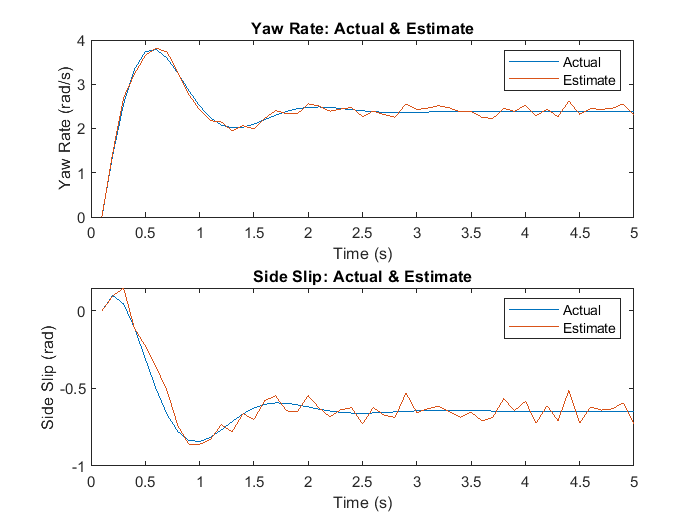

A = [-2.62 12;
    -0.96 -2];
B = [14; 1];

w = 0.1;
Bw = [1;1];

H = [1 0];

% Simulation Initialization
t_end = 5;
dt = 0.1;
t = dt:dt:t_end;
numSamps = length(t);

X = zeros(2, numSamps);
y = zeros(numSamps, 1);
del = 1;

sys = ss(A,B,H,0);
sysd = c2d(sys,dt);

% Dynamic Simulation
for i = 1:numSamps-1
    xdot = A * X(:,i) + B * del;
    X(:,i+1) = X(:,i) + xdot * dt;
    y(i+1) = H * X(:,i+1) + (0.1*randn);
    x = X(:,i+1);
end

A_D = expm(A*dt);

Q_D = [0.5 0; 0 0.5];
R_D = 0.01;


% Preallocation & Initialization
x_hat = zeros(2, numSamps);
P = eye(2);
priorP = zeros(numSamps,2);
postP = zeros(numSamps,2);

for i = 1:numSamps-1
    
    % Time Update (Propagation - a priori)
    x_hat(:,i+1) = A_D * x_hat(:,i) + sysd.B * del;

    P = A_D * P * A_D' + Q_D;
    priorP(i+1,1) = P(1,1);
    priorP(i+1,2) = P(2,2);

    % Measurement Update (Correction - a posteriori)
    K = P * H' * (H*P*H' + R_D)^-1;

    x_hat(:,i+1) = x_hat(:,i+1) + K * (y(i+1) - H * x_hat(:,i+1));

    P = (eye(2) - K*H) * P;
    postP(i+1,1) = P(1,1);
    postP(i+1,2) = P(2,2);

end

KFeig = eig(A-K*H);

figure
subplot(2,1,1)
plot(t,X(1,:))
hold on
plot(t,x_hat(1,:))
title('Yaw Rate: Actual & Estimate')
legend('Actual','Estimate')
xlabel('Time (s)')
ylabel('Yaw Rate (rad/s)')

subplot(2,1,2)
plot(t,X(2,:))
hold on
plot(t,x_hat(2,:))
title('Side Slip: Actual & Estimate')
legend('Actual','Estimate')
xlabel('Time (s)')
ylabel('Side Slip (rad)')


clearvars

- **Part B: **Given the unmodeled addition of the brick, side slip can no longer be accurately estimated.

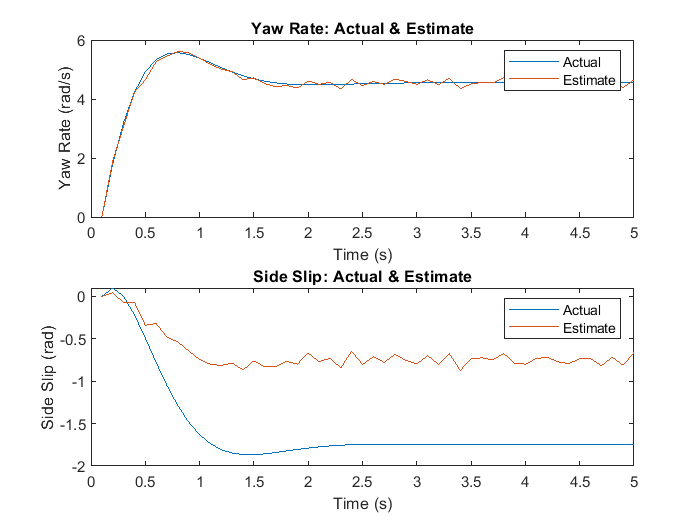

A = [-2.42 4;
    -0.99 -2];
B = [18; 1];

H = [1 0];

% Simulation Initialization
t_end = 5;
dt = 0.1;
t = dt:dt:t_end;
numSamps = length(t);

X = zeros(2, numSamps);
y = zeros(numSamps, 1);
del = 1;

sys = ss(A,B,H,0);
sysd = c2d(sys,dt);

% Dynamic Simulation
for i = 1:numSamps-1
    xdot = A * X(:,i) + B * del;
    X(:,i+1) = X(:,i) + xdot * dt;
    y(i+1) = H * X(:,i+1) + (0.1*randn);
    x = X(:,i+1);
end

A_A = [-2.62 12;
    -0.96 -2];

A_D = expm(A_A*dt);
Q_D = 5*eye(2);
R_D = 0.01;

% Preallocation & Initialization
x_hat = zeros(2, numSamps);
P = eye(2);
priorP = zeros(numSamps,2);
postP = zeros(numSamps,2);

for i = 1:numSamps-1
    
    % Time Update (Propagation - a priori)
    x_hat(:,i+1) = A_D * x_hat(:,i) + sysd.B*del;

    P = A_D * P * A_D' + Q_D;
    priorP(i+1,1) = P(1,1);
    priorP(i+1,2) = P(2,2);

    % Measurement Update (Correction - a posteriori)
    K = P * H' * (H*P*H' + R_D)^-1;

    x_hat(:,i+1) = x_hat(:,i+1) + K * (y(i+1) - H * x_hat(:,i+1));

    P = (eye(2) - K*H) * P;
    postP(i+1,1) = P(1,1);
    postP(i+1,2) = P(2,2);

end

KFeig = eig(A-K*H);

figure
subplot(2,1,1)
plot(t,X(1,:))
hold on
plot(t,x_hat(1,:))
title('Yaw Rate: Actual & Estimate')
legend('Actual','Estimate')
xlabel('Time (s)')
ylabel('Yaw Rate (rad/s)')

subplot(2,1,2)
plot(t,X(2,:))
hold on
plot(t,x_hat(2,:))
title('Side Slip: Actual & Estimate')
legend('Actual','Estimate')
xlabel('Time (s)')
ylabel('Side Slip (rad)')


clearvars

- **Part C: **The following is what $R$ should be:


$$R = \left[\matrix{0.01 & 0 \cr 0 & 0.25}\right]$$


- **Part D: **Changing the value of $Q_D$ associated with side slip changes how biased the estimate is. In order to get the result of the following plot, $Q_D$ should have been:


$$Q_D = \left[\matrix{5 & 0 \cr 0 & 0.05}\right]$$


This provides a noisy estimate of side slip but it is no longer biased.

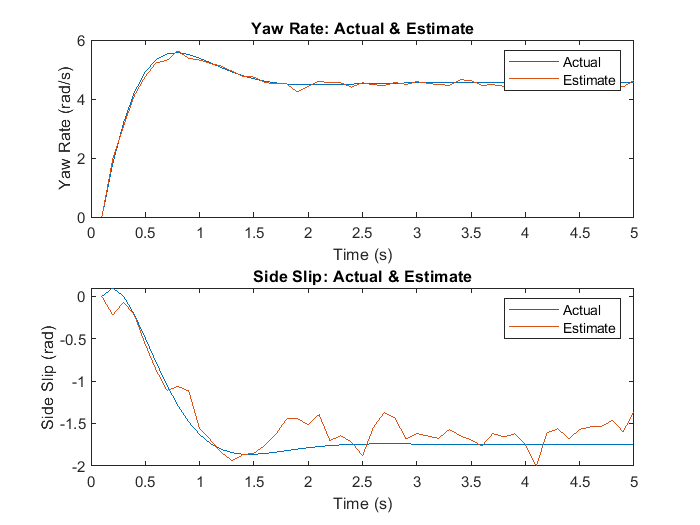

A = [-2.42 4;
    -0.99 -2];
B = [18; 1];

H = eye(2);

% Simulation Initialization
t_end = 5;
dt = 0.1;
t = dt:dt:t_end;
numSamps = length(t);

X = zeros(2, numSamps);
y = zeros(2, numSamps);
del = 1;

% Dynamic Simulation
for i = 1:numSamps-1
    xdot = A * X(:,i) + B * del;
    X(:,i+1) = X(:,i) + xdot * dt;
    y(:,i+1) = H * X(:,i+1) + [(0.1*randn);(0.5*randn)];
    x = X(:,i+1);
end

A_A = [-2.62 12;
    -0.96 -2];

A_D = expm(A_A*dt);
Q_D = [5 0;0 0.05];
R_D = [0.01 0;0 0.25];

sys = ss(A,B,H,0);
sysd = c2d(sys,dt);

% Preallocation & Initialization
x_hat = zeros(2, numSamps);
P = eye(2);
priorP = zeros(numSamps,2);
postP = zeros(numSamps,2);

for i = 1:numSamps-1
    
    % Time Update (Propagation - a priori)
    x_hat(:,i+1) = A_D * x_hat(:,i) + sysd.B*del;

    P = A_D * P * A_D' + Q_D;
    priorP(i+1,1) = P(1,1);
    priorP(i+1,2) = P(2,2);

    % Measurement Update (Correction - a posteriori)
    K = P * H' * (H*P*H' + R_D)^-1;

    x_hat(:,i+1) = x_hat(:,i+1) + K * (y(:,i+1) - H * x_hat(:,i+1));

    P = (eye(2) - K*H) * P;
    postP(i+1,1) = P(1,1);
    postP(i+1,2) = P(2,2);

end

KFeig = eig(A-K*H);

figure
subplot(2,1,1)
plot(t,X(1,:))
hold on
plot(t,x_hat(1,:))
title('Yaw Rate: Actual & Estimate')
legend('Actual','Estimate')
xlabel('Time (s)')
ylabel('Yaw Rate (rad/s)')

subplot(2,1,2)
plot(t,X(2,:))
hold on
plot(t,x_hat(2,:))
title('Side Slip: Actual & Estimate')
legend('Actual','Estimate')
xlabel('Time (s)')
ylabel('Side Slip (rad)')